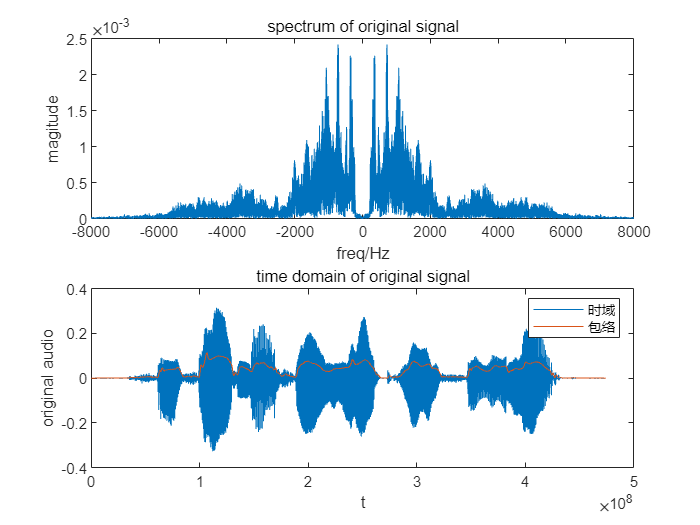

close all;clc;clear;
[x, fs] = audioread ("C_01_02.wav");

N = length(x);
f = linspace(-fs/2, fs/2, N);
xt = (0:N-1)*fs;
but_order = 4;

% SSN
noise = (1-2*rand(N,1));
sig = repmat(x,10,1);
[Pxx,w] = pwelch(sig,[],[],512,fs);
b=fir2(3000,w/(fs/2),sqrt(Pxx/max(Pxx)));
[h, wh] = freqz(b,1,128);
noise = filter(b,1,noise);


% -5dB
Enoise = norm(noise);
Ex = norm(x);
Eknosie = 10^(1/4)*Ex;
k = Eknosie/Enoise;
y = x + k*noise;

% 归一化
Ey = norm(y);
m = Ey/Ex;
y_Final = y./m;


figure
subplot(211);
x_fft = fft(x)/length(x);
plot(f,abs(fftshift(x_fft)));%%%
title('spectrum of original signal');
xlabel('freq/Hz');ylabel('magitude');
subplot(212);

[b,a]=butter(but_order,100/(fs/2));
x_enve=filter(b,a,abs(x));
plot(xt, x, xt, x_enve);%%%
title('time domain of original signal');
xlabel('t');ylabel('original audio');
legend('时域','包络','Location', 'northeast' )

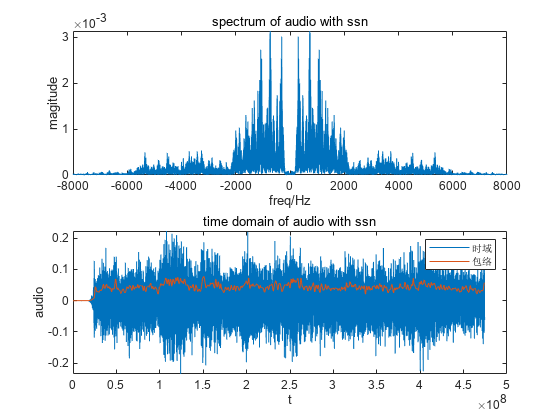


figure
subplot(211);
y_Final_fft = fft(y_Final)/length(y_Final);
plot(f,abs(fftshift(y_Final_fft)));%%%%
title('spectrum of audio with ssn');
xlabel('freq/Hz');ylabel('magitude');
subplot(212);
[b,a]=butter(but_order,100/(fs/2));
y_Final_enve=filter(b,a,abs(y_Final));
plot(xt, y_Final, xt, y_Final_enve);%%%%
title('time domain of audio with ssn');
xlabel('t');ylabel('audio');
legend('时域','包络','Location', 'northeast' )

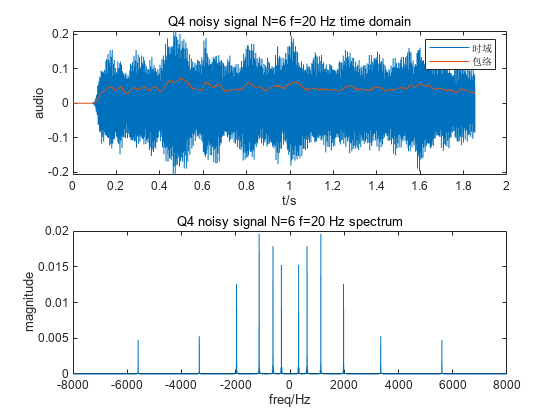

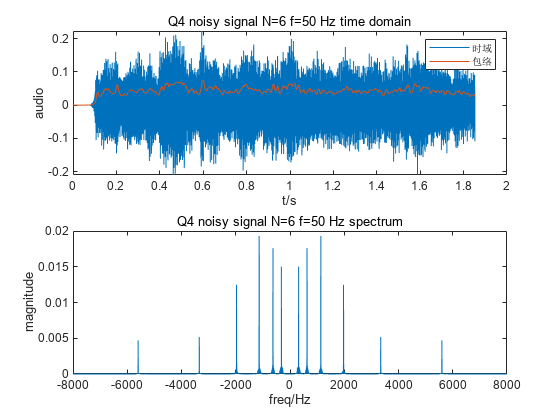

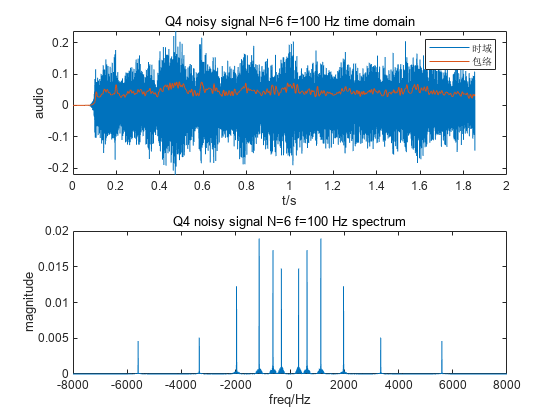

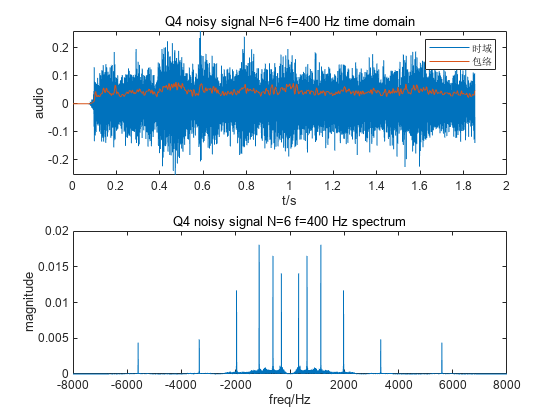


n_bands = 6;
for i = [20 50 100 400]
    y = tone_vocoder(y_Final,n_bands, i,but_order,fs);
    Y = fft(y)/length(y);
    figure;
    subplot(211);
    [b,a]=butter(but_order,100/(fs/2));
    y_enve=filter(b,a,abs(y));
    plot((0:N-1)/fs, y, (0:N-1)/fs, y_enve);
    xlabel("t/s");
    ylabel("audio");
    legend('时域','包络','Location', 'northeast' );
    title(sprintf('Q4 noisy signal N=%d f=%d Hz time domain',n_bands, i));
    subplot(212);
    plot(f,abs(fftshift(Y)));
    title(sprintf('Q4 noisy signal N=%d f=%d Hz spectrum',n_bands, i));
    xlabel('freq/Hz');
    ylabel('magnitude');
    audiowrite(sprintf('Q4 noisy signal N=%d f=%d Hz.wav',n_bands, i),y,fs)
end